clearvars; clc;

dataloc = 'E:/SP_cup/Dataset/ROBOVOX_SP_CUP_2024';  %Dataset location
single_channel_path = fullfile(dataloc,'data','single-channel');
single_enrolls = fullfile(single_channel_path,'enrollment') %fullfile in matlab makes a path

single_enrolls = 'E:\SP_cup\Dataset\ROBOVOX_SP_CUP_2024\data\single-channel\enrollment'

file_1 = 'spk_8-8_16_0_0_d8_ch5.wav';
[x,fs] = audioread(fullfile(single_enrolls,file_1));

soundsc(x,fs)  

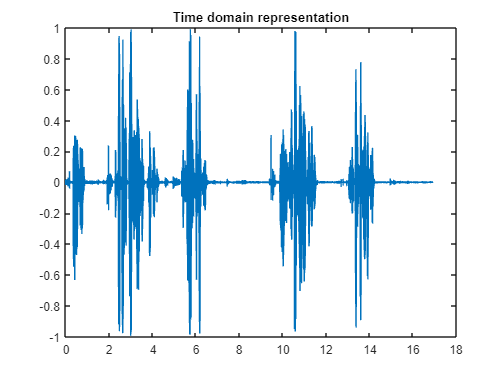

ts = 1/fs;
N = size(x,1);
tmax = (N-1)*ts;
t = 0:ts:tmax;
plot(t,x);
title("Time domain representation");

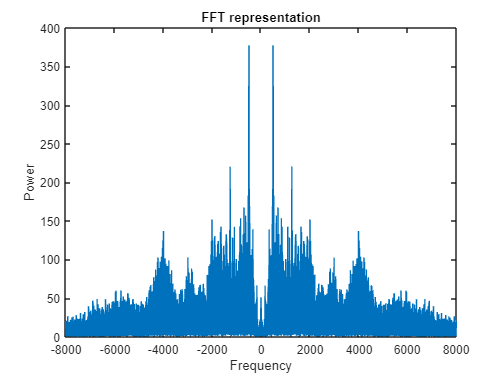

f = -fs/2 : fs/(N-1) : fs/2;
z = fftshift(fft(x));
plot(f, abs(z))
xlabel('Frequency');
ylabel('Power');
title("FFT representation")

% cutoff_frequency = 4000;  % Cutoff frequency for the low-pass filter in Hz
% order = 4;               
% 
% [b, a] = butter(order, cutoff_frequency/(fs/2), 'low');
% 
% low_pass_filtered_audio = filter(b, a, x);   % Apply the low-pass filter to the audio signal

% soundsc(low_pass_filtered_audio,fs)


J = floor(log2(N));
waveletName = 'sym4';  
[c,l] = wavedec(x, J, waveletName);

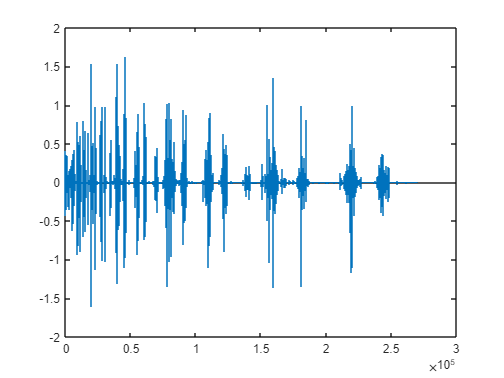

stem(c,'Marker', 'none')

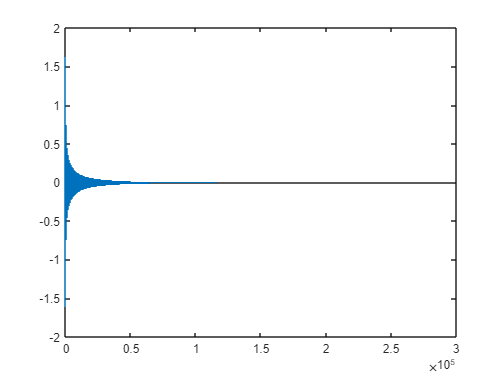


magnitude = abs(c); %get magnitudes
[sorted_magnitudes, idx] = sort(magnitude, 'descend'); % Sort the coefficients and their magnitudes in descending order
c_sorted = c(idx);  
stem(c_sorted,'Marker', 'none')

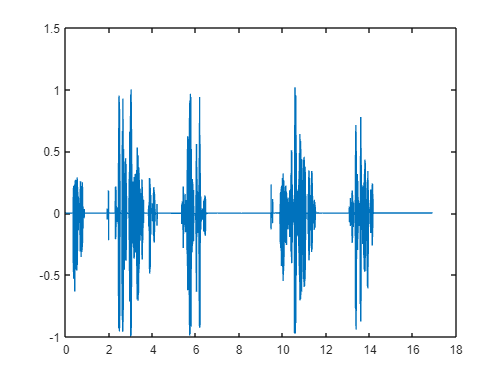

threshold_value = 0.1;
thresholded_coefficients = c;
thresholded_coefficients(abs(c) < threshold_value) = 0;
reconstructed_after_threshold = waverec(thresholded_coefficients, l, 'sym4');

soundsc(reconstructed_after_threshold,fs)

plot(t,reconstructed_after_threshold);

% hold on;
% plot(t,x);
% legend('reconstructed','x');
% hold off;

soundsc(x,fs)  % function to listen to the audio -- (audio, sampling rate)

soundsc(reconstructed_after_threshold,fs)

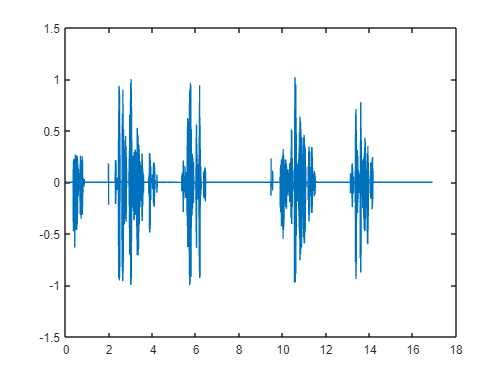

energy = zeros(size(c));
for coefs = 1:length(c)
    if coefs == 1
        energy(coefs) = c_sorted(coefs)^2;
    else
        energy(coefs) = c_sorted(coefs)^2 + energy(coefs-1);
    end
end
energy = energy / max(energy);

index= find(energy >= 0.90,1); %find the number of coefficients for 99% energy

new_coefficients= zeros(size(c_sorted));
for i = 1:index
    new_coefficients(idx(i)) = c_sorted(i);
end
compressed = waverec(new_coefficients, l, 'sym4');

soundsc(compressed,fs)

plot(t,compressed);

soundsc(x,fs) %Noisy one

soundsc(reconstructed_after_threshold,fs)  %my threshold

soundsc(compressed,fs) %keeping 99%